Exercícios:

1) Determine a raiz real de $x^{3,5}=80, com o método das secantes até erro relativo seja 0,1% usando aproximações iniciais de $x_{0}=3$ e  $x_{1}=4$.

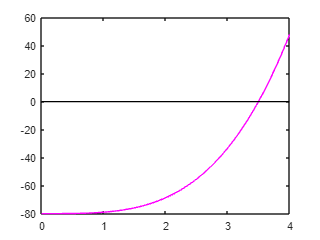

x= 0:0.01:4;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off        

x0 = 3;
x1 = 4;
err_rel = 10;
tol = 0.1/100;

while err_rel > tol
    x = (x0.*fun(x1) - x1.*fun(x0))/(fun(x1) - fun(x0));
    err_rel = abs(x1 - x0)/abs(x0);
    x0 = x1;
    x1 = x;
end

x

x = 3.4974

2) Use o método de Newton-Raphson para encontrar a raiz de $f(x)=e^{-0,5x}(4-x)-2$.

Use aproximações iniciais de $x^{0}=2$, $x^{0}=6$, $x^{0}=8$. Explique os resultados.

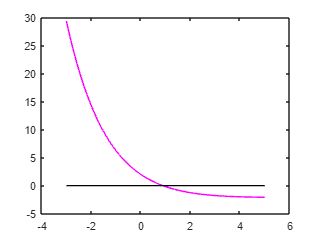

x= -3:0.01:5;
y = fun2(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off        

x0 = 8;
err_rel = 10;
tol = 10^-4;

while err_rel > tol
    x = x0 - fun2(x0)./gfun2(x0);
    err_rel = abs(x - x0)/abs(x);
    x0 = x;
end

x

x = Inf

aprox1 = 0.8857;
aprox2 = inf;
aprox3 = inf;

3) (a) Aplique o método de Newton-Raphson à função $f(x)=\tanh{(x^{2}-9)}$ para calcular sua raiz real conhecida $x^{*}=3$. Use uma aproximação inicial de $x^{0}=3,2$ e faça um mínimo de 4 iterações;

(b)O método convergiu para sua raiz real? Esboce o gráfico, com os resultados para cada iteração.

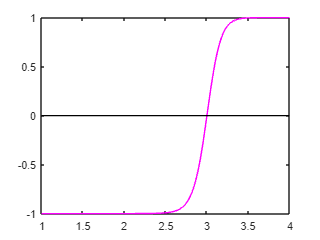

x= 1:0.01:4;
y = fun3(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off        

%a)
x0 = 3.2;
err_rel = 10;
tol = 10^-4;
k = 0;
while err_rel > tol
    k = k+1;
    x = x0 - fun3(x0)/gfun3(x0);
    fk(k, :) = fun3(x0);
    err_rel = abs(x - x0)/abs(x);
    x0 = x;
end

iteracoes = k

iteracoes = 8

fk

fk =     0.8455
    0.8181
    0.7681
    0.6659
    0.4501
    0.1350
    0.0038
    0.0000


x

x = 3.0000


%b)
%Não convergiu.

4) Você está projetando um tanque esférico para armazenar água para uma pequena vila em um país em desenvolvimento. O volume de líquido que ele pode armazenar pode ser calculado por 


$$V = \pi h^{2} \frac{(3R-h)}{3}$$


onde $V$ é o volume $m^{3}$, $h$ é a profundidade no tanque $m$ e $R$ é o raio do tanque $m$.

Se $R=3 \ m$, até qual profundidade $h$ o tanque deve ser enchido para que armazene $30 \ m^{3}$? Use 3 iterações do método de Newton-Raphson para determinar sua resposta. Determine o erro relativo aproximado a cada iteração

x0 = 3;
err_rel = 10;
tol = 10^-4;
k = 0;
while err_rel > tol
    k = k+1;
    x = x0 - fun4(x0)./gfun4(x0);
    err_rel = abs(x - x0)/abs(x);
    x0 = x;
end
iteracoes = k

iteracoes = 3

x

x = 2.0269

**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = x.^3.5 - 80;
end

function f2 = fun2(x)
    f2 = exp(-0.5*x).*(4-x)-2;
end
function g2 = gfun2(x)
    g2 = -2.*exp(-0.5.*x) + exp(-0.5.*x).*x - exp(-0.5.*x);
end
function f3 = fun3(x)
    f3 = tanh(x.^2-9);
end
function g3 = gfun3(x)
    g3 = (sec(x.^2-9).^2).*2.*x;
end
function f4 = fun4(h)
    f4 = pi.*(h.^2).*(3*3 - h)/3 - 30;
end
function g4 = gfun4(h)
    g4 = (18.*pi.*h - 3.*pi.*h^2)/3;
end